# Data Acquisition

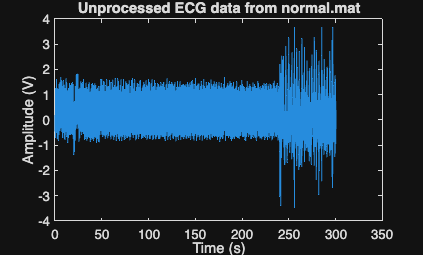

clear;
filename = "normal.mat";
is_unix = true; % CHANGE THIS TO FALSE IF USING WINDOWS
filepath = "data";

if is_unix == true
    filepath = filepath + "/" + filename;
else
    filepath = filepath + "\" + filename;
end


% Load 75100x2 matrix "normal" into the workspace
load(filepath);
t = normal(:,1);
x = normal(:,2);

% Plotting the full span of the unprocessed ECG data
figure;
plot(t,x);
title("Unprocessed ECG data from normal.mat");
xlabel("Time (s)");
ylabel("Amplitude (V)");


% Plotting the resting phase of the ECG data
figure;
plot(t,x);
title("Resting Phase (First 4 Minutes)");
xlabel("Time (s)");
ylabel("Amplitude (V)");
xlim([0,240]);

% Plotting the contracting phase of the ECG data
figure;
plot(t,x);
title("Contracting Phase (Last Minute)");
xlabel("Time (s)");
ylabel("Amplitude (V)");
xlim([240,300]);

fs = 250;

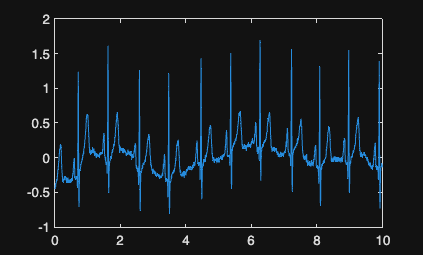

x_sample_clean = x(1:2500);
x_sample_noisy = x(5000:7500);

t_sample_clean = t(1:2500);
t_sample_noisy = t(5000:7500);

plot(t_sample_clean, x_sample_clean);

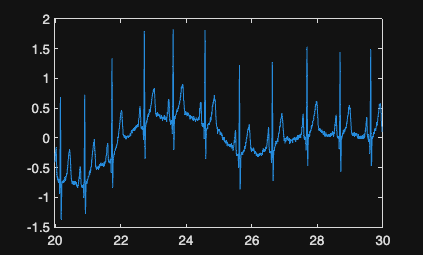


plot(t_sample_noisy, x_sample_noisy);

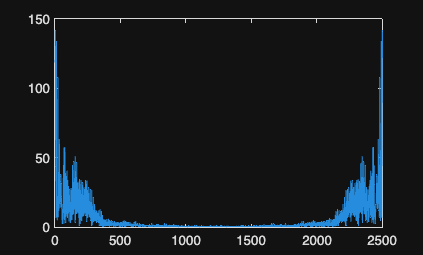


Mag_clean = fft(x_sample_clean);
% xlim([0, 125]);

Mag_noisy = fft(x_sample_noisy);



figure;
plot(abs(Mag_clean));

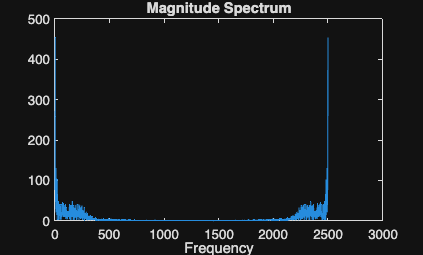

plot(abs(Mag_noisy));
title("Magnitude Spectrum");
xlabel("Frequency");
ylabel("")

% load("data\n_422.mat");
% load("data\n_421.mat");